# Parallel Code Phase Search Algorithm

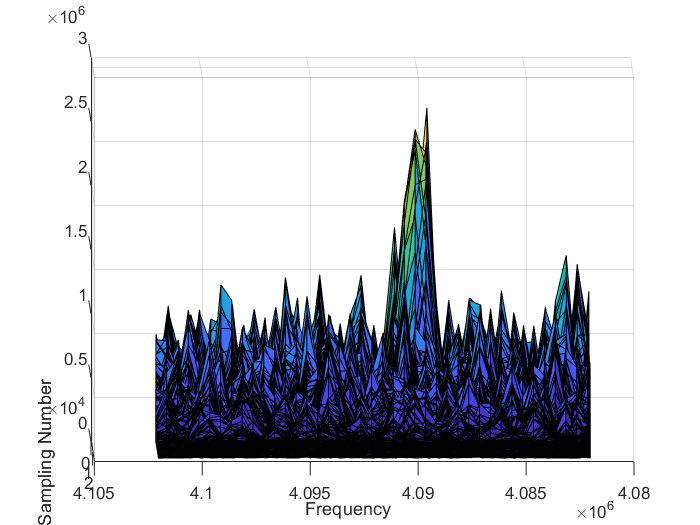

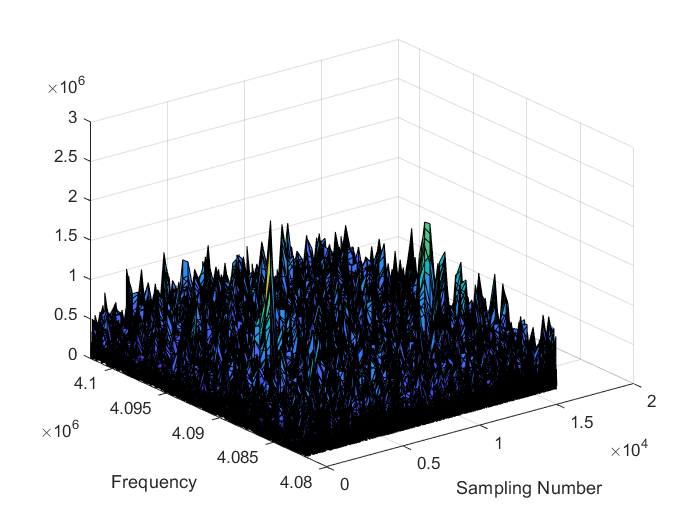

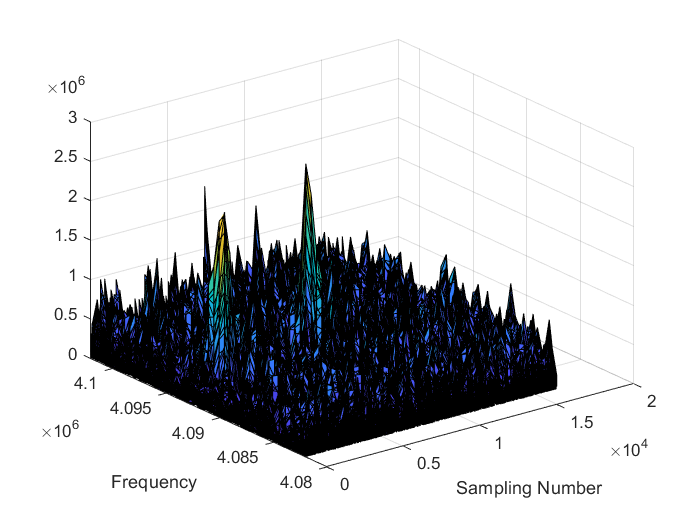

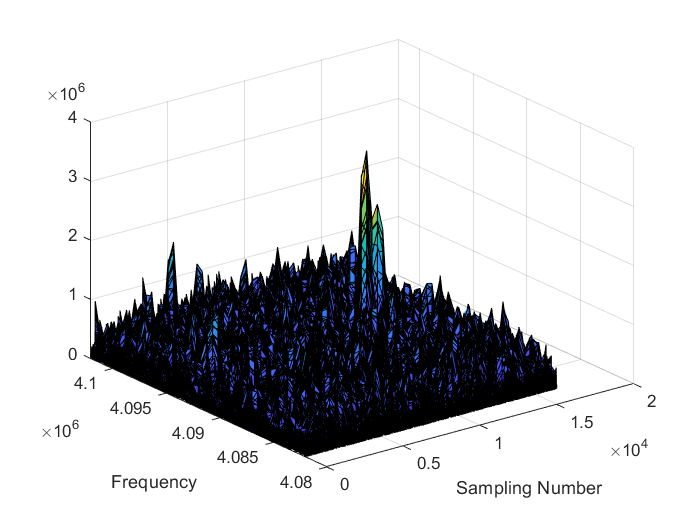

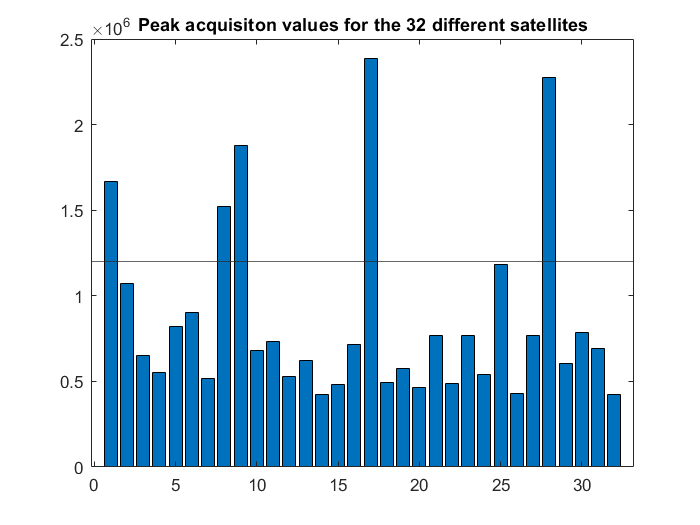

ans = 5×3 table
    prnID    carrierFreq    codePhase
    _____    ___________    _________

      1      4.0895e+06        7688  
      8       4.088e+06        1922  
      9      4.0905e+06        5962  
     17      4.0935e+06       12017  
     28      4.0925e+06        6134  


pcpsAlgorithm

function pcpsAlgorithm
% Loading the data file
intodat = 10;
fid  = fopen('.\SiGe_Bands-L1.dat', 'r');
fseek(fid,intodat, 'bof'); 
idata = fread(fid, 1*16368, 'int8');
%PRN_code = PRN_generation();

% Defining the parameters
N = 16368; % number of samples
f_s = 16368000; % sampling frequency
t_s = 1/f_s;
f_if = 4092000; % intermediate freqeuncy
f_doppler = 10000; % maximum variation due to Doppler shift
f_step = 500; % frequnecy step
freq_bins = (2*f_doppler)/f_step + 1;
acqThreshold = 2.2e6;

% Maintaing vectors for the outputs
cnt = 1;

% Generating the CA codes table
CaCodeTable = generateCaTable(f_s);

% Creaating the array for carrier frequencies
f_c = ones(1,freq_bins);
for step_number = 0:(freq_bins-1)
        f_c(1,step_number + 1) = f_if - f_doppler + f_step*step_number; % current carrier frequency
end

[Xp,Yp] = meshgrid(1:N,f_c(1:freq_bins));
        
for PRN_number = 1:32
    CFFT = transpose(conj(fft(CaCodeTable(PRN_number,:))));
    for step_number = 0:(freq_bins-1)
        cumulative_freq = 2*pi*t_s *f_c(1,step_number + 1);
        sine_data = transpose(sin(cumulative_freq*(0:N-1)));
        cosine_data = transpose(cos(cumulative_freq*(0:N-1)));
        I = sine_data.*idata;
        Q = cosine_data.*idata;
        
        % defining the complex signal
        Y = I + j*Q;
        Y_fft = fft(Y);
        final_processed_singal = ifft(Y_fft.*CFFT);
        output = abs(final_processed_singal).^2;
        results(step_number+1,:) = output;
    end
    %figure(PRN_number);
    %surf(Xp,Yp,results);
    %xlabel("Sampling Number")
    %ylabel("Frequency")
    max_value(1,PRN_number)= max(results,[],'all');
    [max_value(1,PRN_number),freqBinIndex] = max(max(results,[],2));
    [max_value(1,PRN_number),codPhase(1,PRN_number)] = max(max(results));
    
    if(max_value(1,PRN_number)>acqThreshold)
        prnID(cnt,1) = PRN_number;
        carrierFreq(cnt,1) = f_c(freqBinIndex);
        codePhase(cnt,1) = codPhase(1,PRN_number);
        cnt=cnt+1;
        figure(PRN_number);
        title(sprintf('Acquisition plot for PRN %f',PRN_number))
        surf(Xp,Yp,results);
        xlabel("Sampling Number")
        ylabel("Frequency")
    end
    
end
x = 1:32;
bar(max_value - 1e6)
hold on
yline(1.2e6)
title('Peak acquisiton values for the 32 different satellites')
hold off

%Displaying the acquisition results
table(prnID,carrierFreq,codePhase)
end


function CaCodeTable = generateCaTable(sampling_freq)
% Function for generating discretized 1023 chips long PRN code.
% The function takes input for the satellite vehicle number 
% and the sampling frequency in MHz.   
%----------------------------------------------------------------------
%   Inputs:
% 
%        sv_number:   Satellite vehicle number whose PRN is to be 
%                     generated            
%
%            delay:   Delay in the PRN chip
%
%   samplling_freq:   Sampling frequency of the RF frontend 
%
%----------------------------------------------------------------------
%   Outputs:
%
%           CaCode:    Discretized 1023 chips long PRN code.
%----------------------------------------------------------------------


    % initializing the shift registers and storing satellite
    % PRN references for different SV numbers
    f_chip = 1.023e6;
    f_sampling = sampling_freq;
    
    % total number of CA codes received in 1ms
    n = f_sampling/1000;
    CaCodePrimary = ones(32,1023);
    shift_register1 = ones(1,10);
    shift_register2 = ones(1,10);
    satellitePrnRef = [2 6;3 7;4 8;5 9;1 9;2 10;1 8;2 9;3 10;2 3;3 4;5 6;...
                       6 7;7 8;8 9;9 10;1 4;2 5;3 6;4 7;5 8;6 9;1 3;4 6;5 ... 
                       7;6 8;7 9;8 10;1 6;2 7;3 8;4 9];
    
    for i=1:32
        for j=1:1023
        % first, storing the output for P1, which later becomes 
        % the first index of the shift register of P1 
        a1 = mod((shift_register1(3)+shift_register1(10)),2);
        a10 = shift_register1(10);
        
        % shifting the register for P1
        shift_register1 = circshift(shift_register1,1);
        shift_register1(1) = a1;
        
         % taking xor of eliminated index of P1 with satellite
        % specific space vehicle(SV) numbers
        i1 = satellitePrnRef(i,1);
        i2 = satellitePrnRef(i,2);
        CaCodePrimary(i,j) = mod((a10 + shift_register2(i1) + shift_register2(i2)),2);
        if CaCodePrimary(i,j) == 0
            CaCodePrimary(i,j) = -1;
        end
        
        % now, storing the output of P2 and shifting the 
        % shift register for P2
        a2 = mod((shift_register2(2)+shift_register2(3)+shift_register2(6)...
            +shift_register2(8)+shift_register2(9)+shift_register2(10)),2);
        shift_register2 = circshift(shift_register2,1);
        shift_register2(1) = a2;
        end
        codeValueIndex = ceil(((1:n)*f_chip)/f_sampling);
        codeValueIndex(end) = 1023;
        CaCodeTable(i,:) = CaCodePrimary(i,codeValueIndex);
    end
    
end